# Robot Morphology

Remember:

Team group 11k: Antonio & Juan

Link: https://drive.matlab.com/sharing/......your

## 6R Robot. Puma 560

Before start the exercise see the videos: 

[https://youtu.be/ArzP7rh4_9Q](https://youtu.be/ArzP7rh4_9Q)

## Call the Wired Robot object and plot it

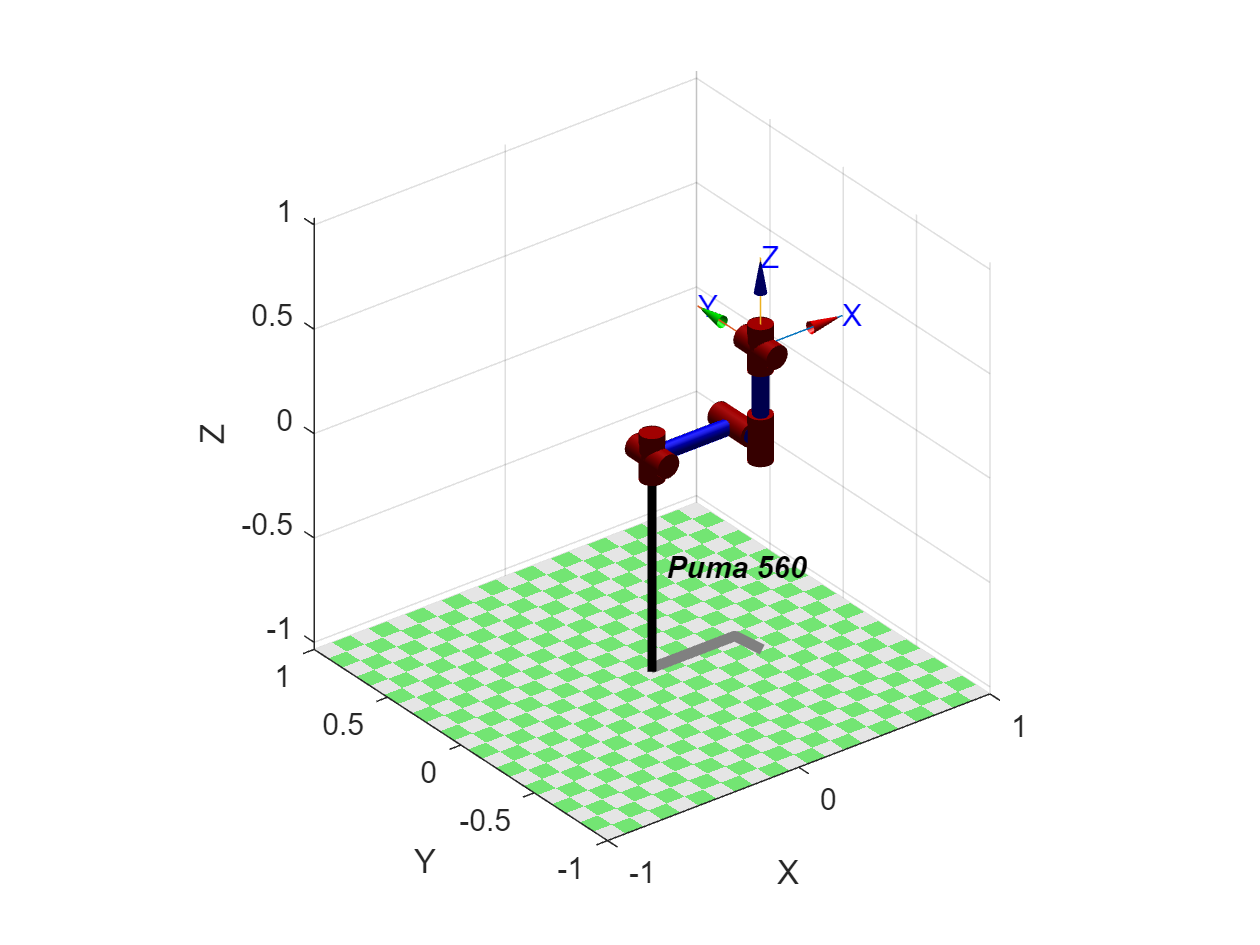

close
clear
mdl_puma560 % Invoque the puma object from the RTB
p560.plot(qz) % qr is the joint vector 1x6. Try qr, qn, any within the limits

Work with the wire model and change the point of view. 

See: https://es.mathworks.com/help/matlab/creating_plots/setting-the-viewpoint-with-azimuth-and-elevation.html

close all
p560.plot(qz)
view([-42.61 46.25])

## Play with the teach 

Modify the joint angle [q1q2 q3 q4 q5 q6] ). It is a kind of Joystick.

Pay attention to [ x y  z].

[ax ay az] are no relevant for the exercise.

p560.teach('approach')

## Moving the Robot

clear all
close all
mdl_puma560

Declare a joint motion by adding rows

Q=zeros(100,6); % at the moment no motion

See the Joint 1 limits

q1_limits=p560.links(1, 1).qlim 

Build the joint's motion. Firts only Joint #1

q1=linspace(q1_limits(1),q1_limits(2),100)';
Q=[q1 Q(:,2:6)]


p560.plot(Q,'jaxes')

## Play with the plot options

Start getting familiar with options of the RTB tools/functions

Type: help plot \  Other functions named plot \ SerialLink/plot

and visit: robot.pdf file: [https://atenea.upc.edu/mod/url/view.php?id=4184725](https://atenea.upc.edu/mod/url/view.php?id=4184725)

or at: https://petercorke.com/toolboxes/robotics-toolbox/

And search for: ETS2.plot

### Moving two joints. See above

q2_limits=p560.links(1, 2).qlim 
q2=linspace(q2_limits(1),q2_limits(2),100)';
Q12=[q1 q2 Q(:,3:6)];

Options: Add a trail to see the trajectory, display the join axis, make biger or smaller the robot

close all
mdl_puma560
p560.plot(Q12,'trail','--','jaxes','zoom',2) %% Play outside the mlx file to see it: copy the setence in Command Window

Play with other options to get familiar with. You must! becouse all along the course it will be necesary

## Recovering End efector position

Use function 'fkine' for recovering the finger tips of the robot.

In next sessionI I will explain and derive  this function

T=p560.fkine(Q12); % Forward Kinematics to be explained. Given Theta's (q's) obtain the robot EE position
ft=[T.t] % to get only the position
figure
plot3(ft(1,:),ft(2,:), ft(3,:))
view(0,40)

## Working area

clear all
close all
mdl_puma560
q2_limits=p560.links(1, 2).qlim 
q2=linspace(q2_limits(1),q2_limits(2),100)';
Q= [zeros(100,1) linspace(q2_limits(1),q2_limits(2),100)' zeros(100,4) ]
figure
hold on
v = [-1 -0.1501 -1 ; 1 -0.1501 -1 ; 1 -0.1501 1; -1 -0.1501 1];
f = [1 2 3 4];
patch('Faces',f,'Vertices',v,'FaceColor','blue','FaceAlpha',.3)
title ('Antonio-G11')
p560.plot(Q,'trail','--','jaxes','zoom',2,'movie','2M.mp4')
T=p560.fkine(Q);
ft=[T.t]

## IRB140 exercise

Get a joint sequence movement to recover the work space as shown in the figure. See video rb140_WS_Solution.mp4.

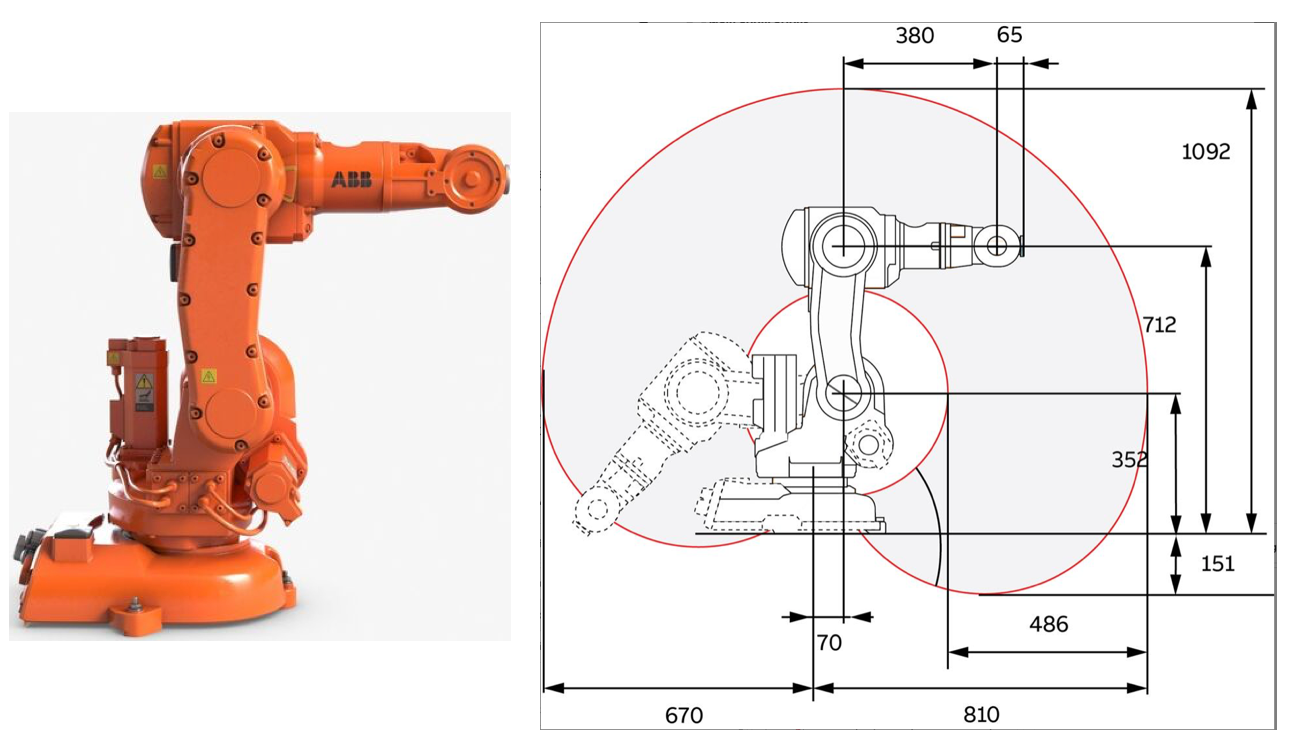

Deliverable to be uploaded in ATENEA:

1.- Make a movie showing the workspace of the IRB140 ABB  robot manipulator.

2.- The link of your Robotica_23_24_1Q shared folder. Keep organize your folders.

Notice:

The title of the figure ought contain the names and group you belong.

### Step 1: Invoque IRB140 

clear
close all
mdl_irb140
irb140.plot(qr) % qr is the joint vector 1x6. Try qr, qn, any within the limits


### Step 2: Plot the IRB 140

irb140.plot(qz,'zoom',2, 'view',[0 0])

Pay attention to home position of the ABB Drawing and the wired model of the RTB

To think about

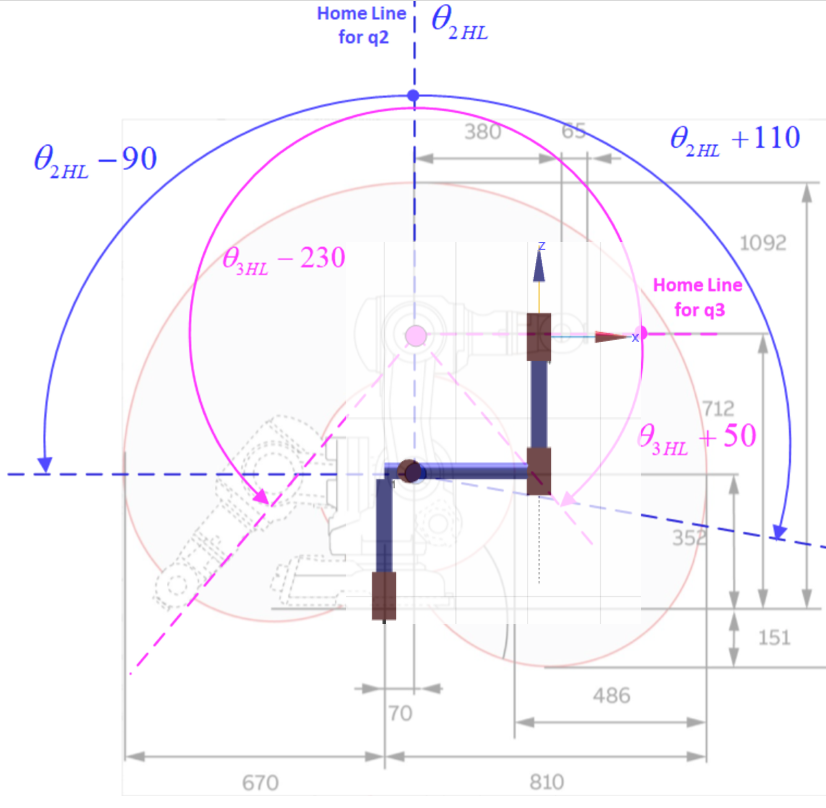

### Step 3: Use the teach

irb140.teach('approach')

### Step 4: Fill the table

Understand the numbers that appears in the following table and fill/create a matrix with the irb140RTB angles.

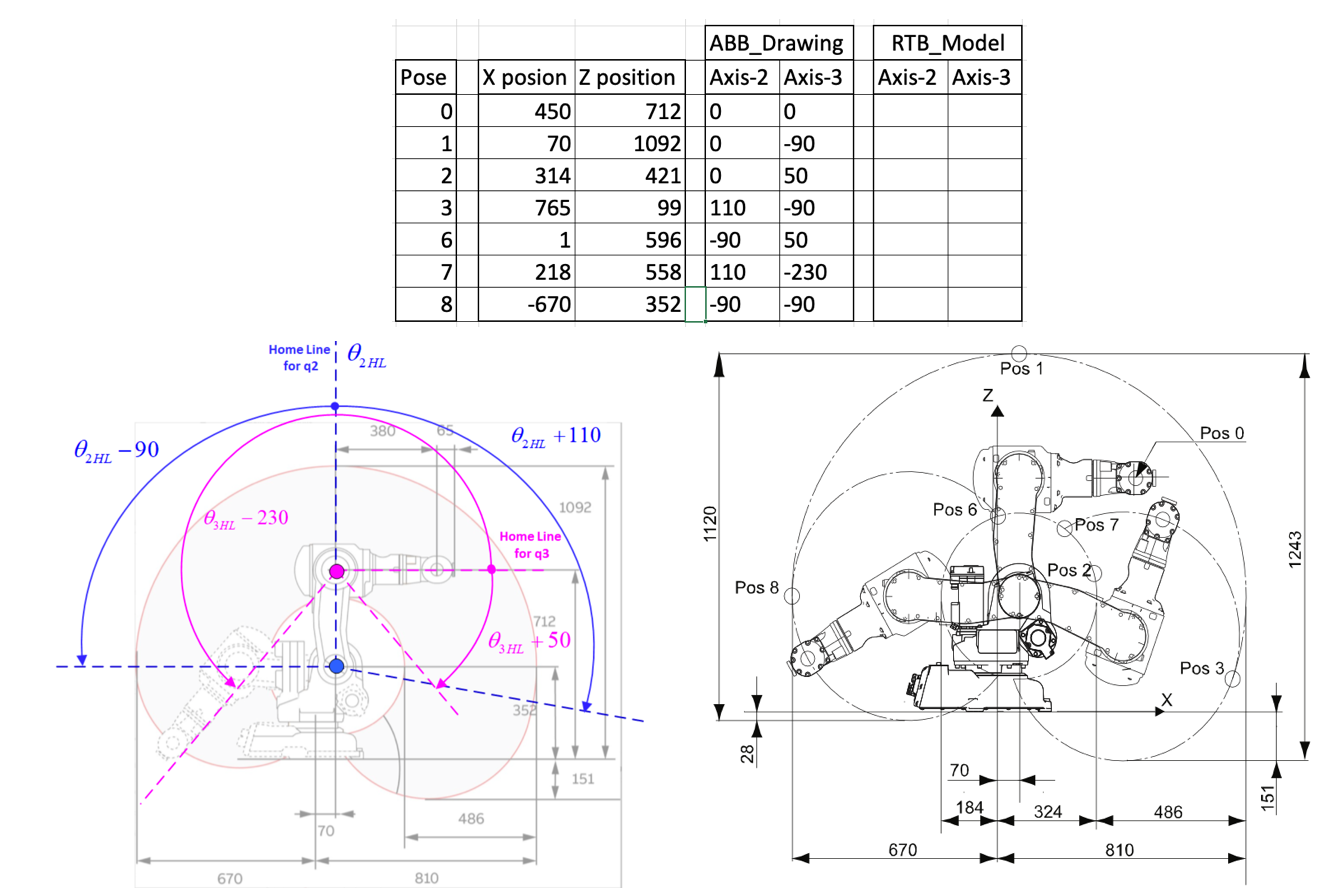

## Step5: Moving the Robot

Declare a joint motion by adding rows

clear all
close all
mdl_irb140

 
robot = 
 
IRB 140 [ABB]:: 6 axis, RRRRRR, stdDH, slowRNE                   
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|      0.352|       0.07|    -1.5708|          0|
|  2|         q2|          0|       0.36|          0|          0|
|  3|         q3|          0|          0|     1.5708|          0|
|  4|         q4|       0.38|          0|    -1.5708|          0|
|  5|         q5|          0|          0|     1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


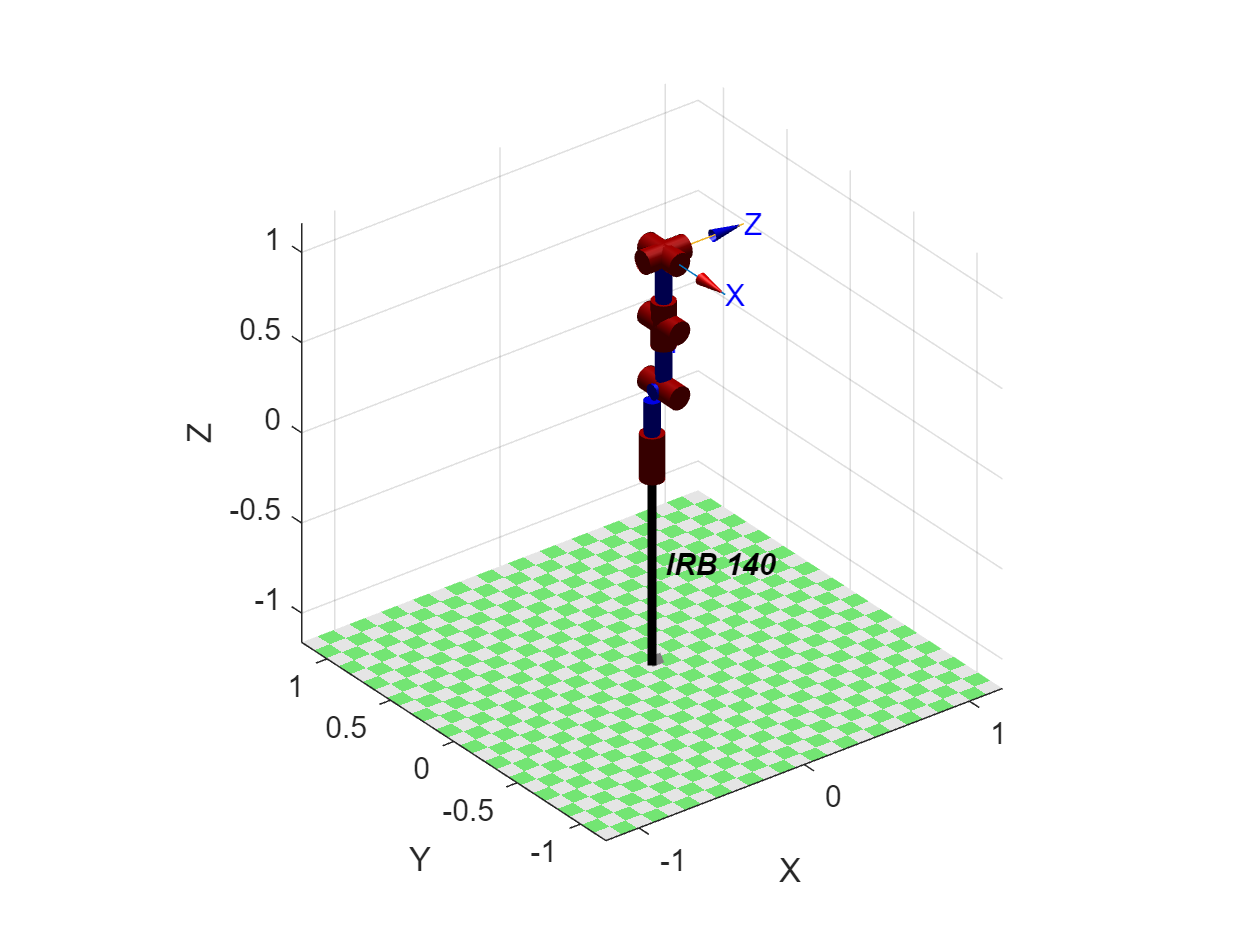

irb140.plot(qr) % qr is the joint vector 1x6. Try qr, qn, any within the limits

Q = zeros(120,6)  % at the moment no motion

Q =      0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


q21 = linspace(-pi, pi/9, 20)

q21 =    -3.1416   -2.9579   -2.7742   -2.5904   -2.4067   -2.2230   -2.0393   -1.8556   -1.6718   -1.4881   -1.3044   -1.1207   -0.9370   -0.7532   -0.5695   -0.3858   -0.2021   -0.0184    0.1653    0.3491


q22 = repmat(pi/9, 1, 20)

q22 =     0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491


q23 = repmat(pi/9, 1, 20)

q23 =     0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491


q24 = linspace(pi/9, -pi, 20)

q24 =     0.3491    0.1653   -0.0184   -0.2021   -0.3858   -0.5695   -0.7532   -0.9370   -1.1207   -1.3044   -1.4881   -1.6718   -1.8556   -2.0393   -2.2230   -2.4067   -2.5904   -2.7742   -2.9579   -3.1416


q25 = repmat(-pi, 1, 20)

q25 =    -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416


q26 = linspace(-pi, -pi/12, 20)

q26 =    -3.1416   -2.9900   -2.8385   -2.6869   -2.5353   -2.3838   -2.2322   -2.0806   -1.9290   -1.7775   -1.6259   -1.4743   -1.3228   -1.1712   -1.0196   -0.8681   -0.7165   -0.5649   -0.4134   -0.2618


q31 = repmat(-3*pi/4, 1, 20)

q31 =    -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562


q32 = linspace(-3*pi/4, -pi, 20)

q32 =    -2.3562   -2.3975   -2.4389   -2.4802   -2.5215   -2.5629   -2.6042   -2.6456   -2.6869   -2.7282   -2.7696   -2.8109   -2.8522   -2.8936   -2.9349   -2.9762   -3.0176   -3.0589   -3.1003   -3.1416


q33 = linspace(pi, pi/2, 20)

q33 =     3.1416    3.0589    2.9762    2.8936    2.8109    2.7282    2.6456    2.5629    2.4802    2.3975    2.3149    2.2322    2.1495    2.0668    1.9842    1.9015    1.8188    1.7361    1.6535    1.5708


q34 = repmat(pi/2, 1, 20)

q34 =     1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708


q35 = linspace(pi/2, -pi/4, 20)

q35 =     1.5708    1.4468    1.3228    1.1988    1.0748    0.9507    0.8267    0.7027    0.5787    0.4547    0.3307    0.2067    0.0827   -0.0413   -0.1653   -0.2894   -0.4134   -0.5374   -0.6614   -0.7854


q36 = repmat(-pi/4, 1, 20)

q36 =    -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854


q2 = [q21 q22 q23 q24 q25 q26]

q2 =    -3.1416   -2.9579   -2.7742   -2.5904   -2.4067   -2.2230   -2.0393   -1.8556   -1.6718   -1.4881   -1.3044   -1.1207   -0.9370   -0.7532   -0.5695   -0.3858   -0.2021   -0.0184    0.1653    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491


q3 = [q31 q32 q33 q34 q35 q36]

q3 =    -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3975   -2.4389   -2.4802   -2.5215   -2.5629   -2.6042   -2.6456   -2.6869   -2.7282   -2.7696   -2.8109   -2.8522   -2.8936   -2.9349   -2.9762   -3.0176   -3.0589   -3.1003   -3.1416    3.1416    3.0589    2.9762    2.8936    2.8109    2.7282    2.6456    2.5629    2.4802    2.3975


q1 = zeros(1,120)

q1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


q4 = zeros(1,120)

q4 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


q5 = zeros(1,120)

q5 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


q6 = zeros(1,120)

q6 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Q = [q1;q2;q3;q4;q5;q6]'

Q =          0   -3.1416   -2.3562         0         0         0
         0   -2.9579   -2.3562         0         0         0
         0   -2.7742   -2.3562         0         0         0
         0   -2.5904   -2.3562         0         0         0
         0   -2.4067   -2.3562         0         0         0
         0   -2.2230   -2.3562         0         0         0
         0   -2.0393   -2.3562         0         0         0
         0   -1.8556   -2.3562         0         0         0
         0   -1.6718   -2.3562         0         0         0
         0   -1.4881   -2.3562         0         0         0


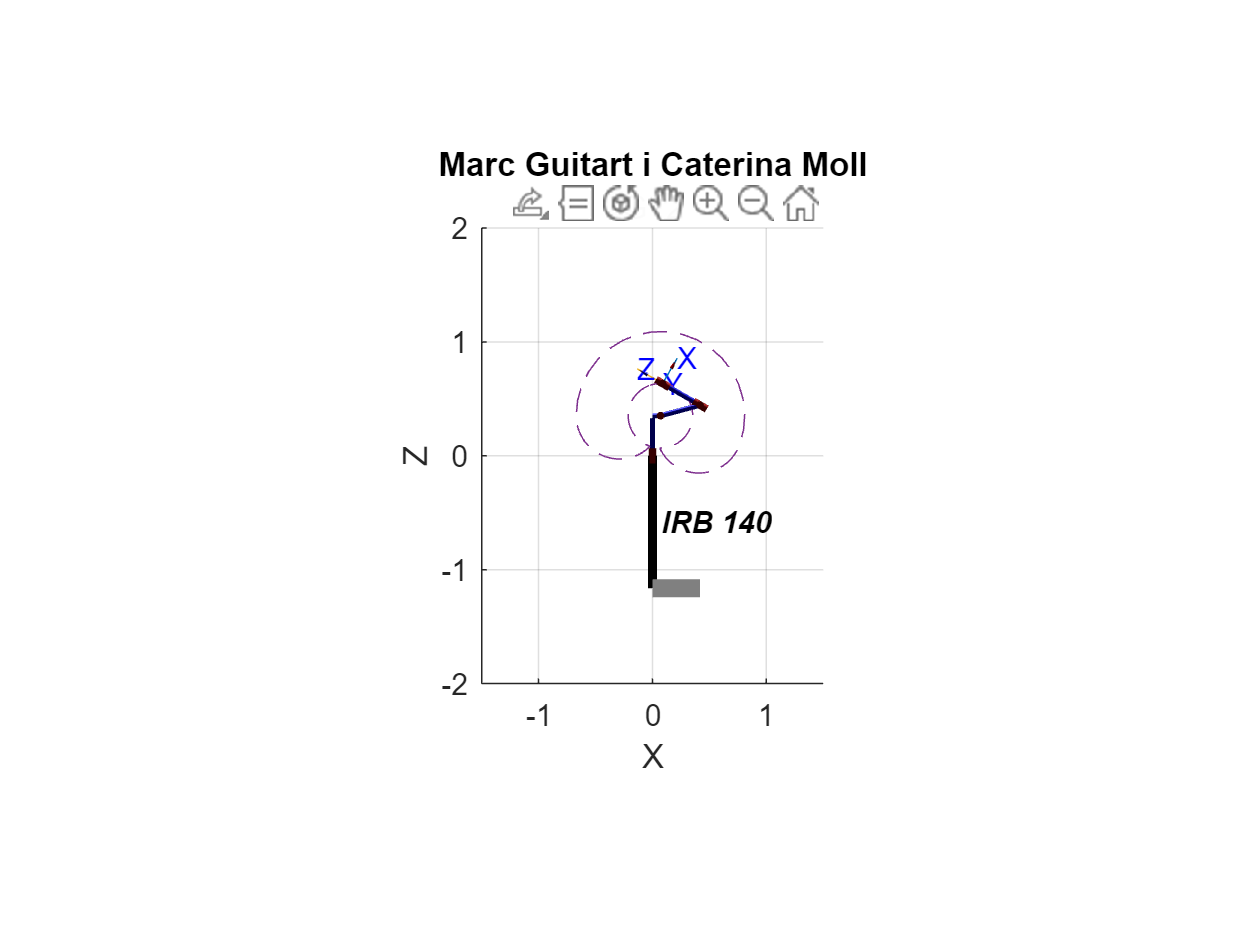

Animate: saving video --> Marc_Caterina.mp4 with profile 'MPEG-4'


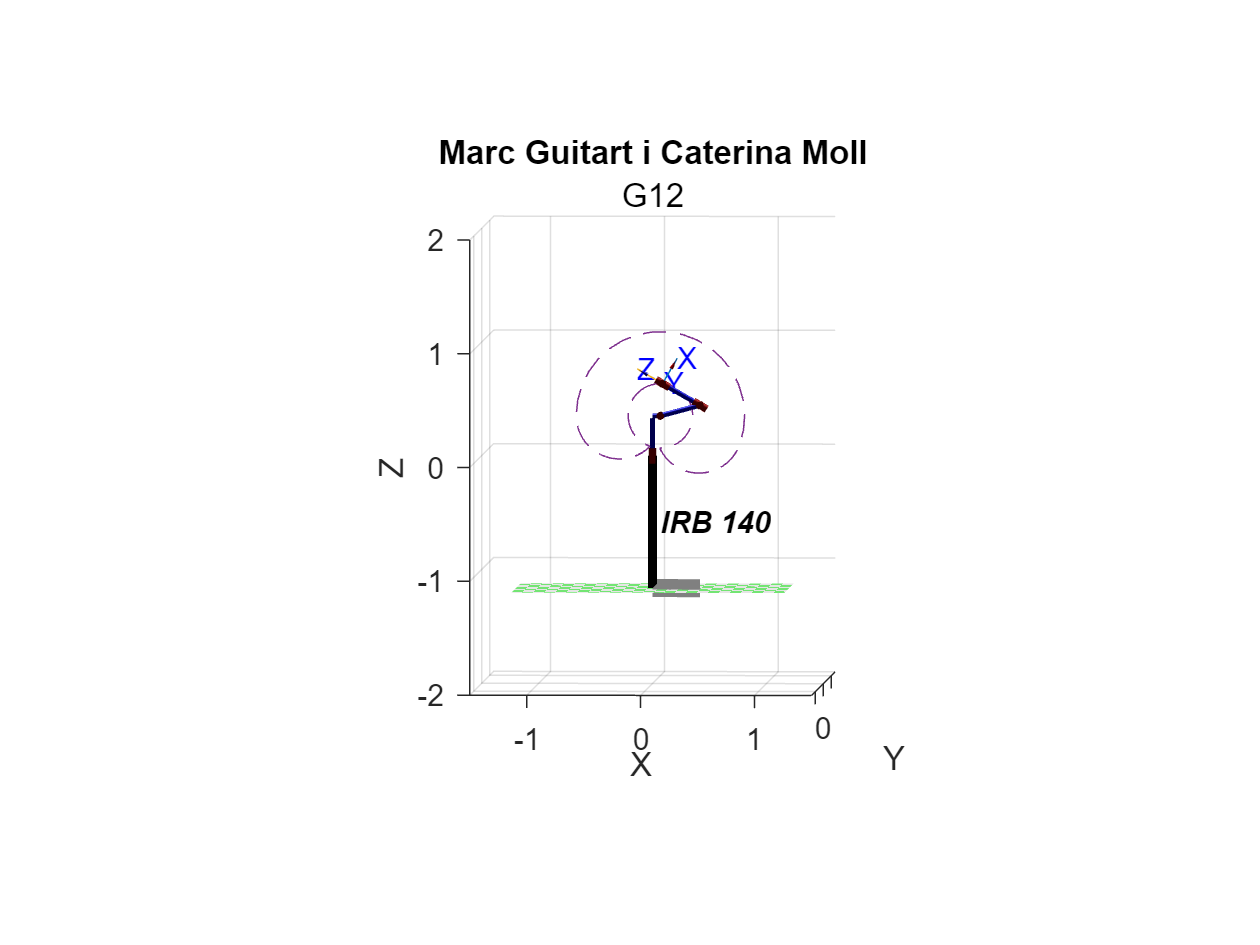

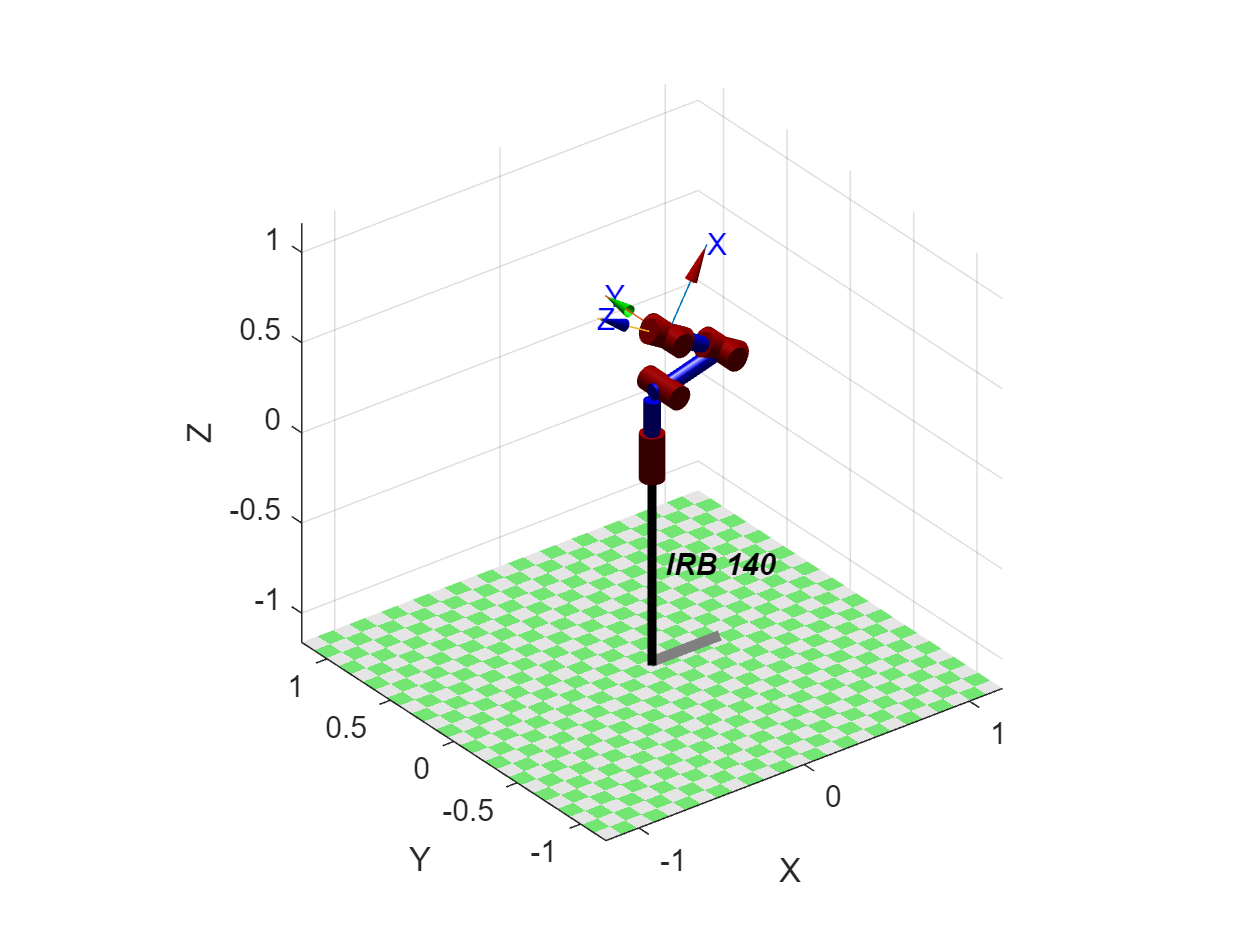

figure 
hold on
title('Marc Guitart i Caterina Moll')
subtitle ('G12')
xlim([-1.5 1.5])
ylim([-3 3])
zlim([-2 2])
irb140.plot(Q,'trail', '--', 'zoom', 2, 'view', [0 0], 'movie', 'Marc_Caterina.mp4')